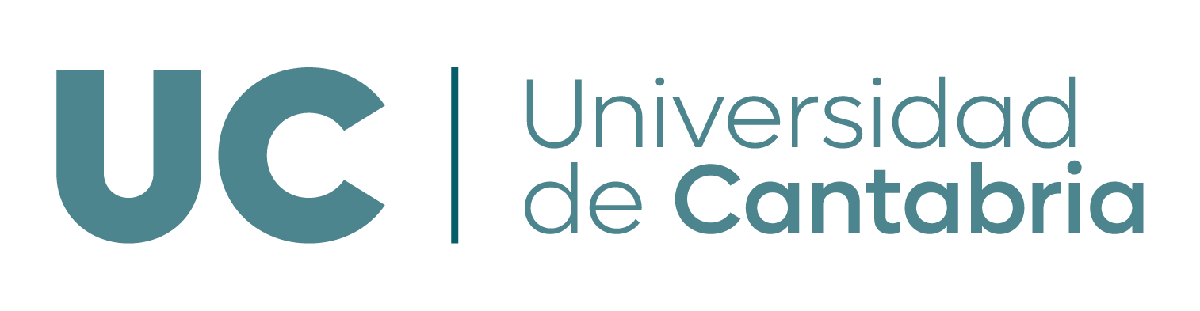

***Grado en Ingeniería en Tecnologías Industriales***

**G414: Álgebra y Geometría**

# **Guion MATLAB: Espacios vectoriales**

*Sara Pérez Carabaza (sara.perezcarabaza@unican.es)*

*Valvanuz Fernández Quiruelas (valvanuz.fernandez@unican.es). *

**Objetivos**

- Determinar si un conjunto de vectores es libre o ligado

- Obtener una base de un subespacio

- Matriz cambio de base

- Pasar de la forma implícita de un subespacio a la paramétrica y viceversa

- Suma e intersección de subespacios

- Hallar el subespacio suplementario.

**Funciones de MATLAB utilizadas en este guion: **`rank, null, rref`

 format rat
clear all;

## **1. Dependencia e independencia lineal**

### **Método 1****: matriz escalonada **

Sea el conjunto de vectores $$S=\lbrace (5,-9,6,4), (-3,4,-2,-1), (0,-7,8,7), (2,0,4,1)\rbrace$$de $\mathbb{R}^4$. Sabemos que el conjunto $S$ será libre (o linealmente independiente) si la única manera de expresar el vector  nulo como combinación lineal de los vectores de $S$ es que todos los coeficientes de la combinación lineal sean nulos. Esto equivale a comprobar que el sistema homogéneo que tiene por matriz  de coeficientes $A$ los vectores de $S$, colocados por columnas, tenga tan sólo la solución trivial (si tuviera infinitas soluciones, $S$ sería un conjunto ligado).


$$
\alpha_1
\left(\begin{array}{c}
     5\\  
     -9\\  
     6\\  
     4\end{array}\right)
+\alpha_2\left(\begin{array}{c}
     -3\\  
     4\\  
     -2\\  
     -1\end{array}\right)
+\alpha_3 \left(\begin{array}{c}
     0\\  
     -7\\  
     8\\  
     7\end{array}\right)
+\alpha_4\left(\begin{array}{c}
     2\\  
     0\\  
     4\\  
     1\end{array}\right)=
\left(\begin{array}{cccc}
     5 & -3 & 0 & 2\\  
     -9 & 4 & -7 & 0\\  
     6 & -2 & 8 & 4\\  
     4 & -1 & 7 & 1\end{array}\right)
\left(\begin{array}{cccc}
     \alpha_1 \\  
   \alpha_2 \\  
     \alpha_3\\  
     \alpha_4\end{array}\right)
=\left(\begin{array}{cccc}
    0 \\  
   0 \\  
     0\\  
     0\end{array}\right)$$


 En realidad, para estudiar la dependencia de un conjunto de vectores estudiamos el tipo de solución de un sistema lineal homogéneo. Los sistemas homogéneos siempre son compatibles, luego únicamente es necesario estudiar si el sistema es SCI (vectores ligados) o SCD (vectores libres). Luego bastará con comprobar si el rango de la matriz de vectores por columnas coincide con el número de columnas. 

% defino los vectores del conjunto
u1 = [5 -9 6 4]';
u2 = [-3 4 -2 -1]';
u3 = [0 -7 8 7]';
u4 = [2 0 4 1]';

% clasifico el sistema homogéneo de interés
A = [u1 u2 u3 u4]  % matriz de coefs. 
rank(A)  % R-F: S.C.I. -> el conjunto S es ligado

El comando *rank *nos indica cuál es el número de vectores independientes. En este caso tenemos 4 vectores y rango 3, luego el conjunto de 4 vectores es ligado, por lo que sabemos que al menos un vector puede expresarse como combinación lineal del resto de vectores. El rango de 3 nos indica que el mayor subconjunto libre de vectores de S que podemos escoger es de 3 vectores. Pueden existir varios grupos de 3 vectores libres. Una manera fácil de encontrar un grupo de 3 vectores libres es a través de la escalonada reducida de la matriz que forman los vectores al colocarlos por columnas, los vectores de las columnas pivotales formarán un conjunto libre. 

rref(A)  % identifico u1, u2 y u4 como l.i. (columnas pivotales)

Las columnas pivotales son la 1, 2 y 4. Luego los vectores $$S=\lbrace (5,-9,6,4), (-3,4,-2,-1),  (2,0,4,1)\rbrace$$forman un conjunto libre y por tanto deberán tener rango 3. Vamos a comprobarlo:

rank(A(:,[1 2 4]))%subconjunto de 3 vectores l.i. (u1, u2 y u4)

Además de permitirnos identificar rápidamente un subconjunto de vectores libres, la matriz escalonada equivalente también nos da información de las relaciones de dependencia de los vectores de un conjunto. Al tratarse $S$ de un conjunto ligado, esto nos asegura que algunos de los vectores pueden expresarse como C.L. del resto. Específicamente, la matriz escalonada reducida nos permite identificar fácilmente como expresar las columas no pivotales como C.L de los vectores de las columnas pivotales. En este ejemplo la única columna no pivotal (la tercera) es el vector [3 5 0 0], podemos observar fácilmente en la matriz escalonada reducida como este vector se obtiene como: multiplicando la primera columna por 3 y sumando la segunda columna multiplicada por 5. Comprobémoslo:

% podemos expresar el vector u3 como combinación lineal del resto:
u3
3*u1+5*u2

***Nota******:*** *Siempre colocaremos los vectores de cualquier conjunto del que queramos estudiar su dependencia/independencia lineal en columnas. Esto es importante ya que al escalonar la matriz las relaciones  entre los vectores columnas se mantienen (pero esto no es así para los vectores fila).*

### **Método 2: resolución sistema lineal homogéneo**

Otro método para hallar las relaciones de dependencia de un conjunto de vectores es resolviendo el sistema lineal homogéneo $A\vec{x}=\vec{0}$, donde $A$ es la matriz con los vectores del conjunto en columas. 


$$
\alpha_1
\left(\begin{array}{c}
     5\\  
     -9\\  
     6\\  
     4\end{array}\right)
+\alpha_2\left(\begin{array}{c}
     -3\\  
     4\\  
     -2\\  
     -1\end{array}\right)
+\alpha_3 \left(\begin{array}{c}
     0\\  
     -7\\  
     8\\  
     7\end{array}\right)
+\alpha_4\left(\begin{array}{c}
     2\\  
     0\\  
     4\\  
     1\end{array}\right)=
\left(\begin{array}{cccc}
     5 & -3 & 0 & 2\\  
     -9 & 4 & -7 & 0\\  
     6 & -2 & 8 & 4\\  
     4 & -1 & 7 & 1\end{array}\right)
\left(\begin{array}{cccc}
     \alpha_1 \\  
   \alpha_2 \\  
     \alpha_3\\  
     \alpha_4\end{array}\right)
=\left(\begin{array}{cccc}
    0 \\  
   0 \\  
     0\\  
     0\end{array}\right)$$


Para resolver sistema lineales homogéneos el comándo `null` nos será muy útil. Como ya hemos visto, si el sistema es SCD (y por tanto el conjunto de vectores fuera libre) entonces solo tendrá la solución trivial y `null` nos devolvería un vector vacio. Para SCI como este ejemplo, la función `null` nos dará un vector por cada parámetro libre.

rank(A)%SCI, 1 parámetro libre
null(A, 'rational') % relación de dependencia: -3*u1-5*u2+1*u3+0*u4 = 0

La solución del sistema lineal homogéneo son las combinaciones lineales de los vectores devueltos por la función `null`. En este ejemplo:


$$\left(\begin{array}{cccc}
     \alpha_1 \\  
   \alpha_2 \\  
     \alpha_3\\  
     \alpha_4\end{array}\right)=
\lambda \left(\begin{array}{cccc}
    -3 \\  
   -5 \\  
    1\\  
     0\end{array}\right)$$


El SCI tiene infinitas soluciones, dando el valor $\lambda=1
$ obtenemos una de ellas:


$$
-3
\left(\begin{array}{c}
     5\\  
     -9\\  
     6\\  
     4\end{array}\right)
-5\left(\begin{array}{c}
     -3\\  
     4\\  
     -2\\  
     -1\end{array}\right)
+1 \left(\begin{array}{c}
     0\\  
     -7\\  
     8\\  
     7\end{array}\right)
+0\left(\begin{array}{c}
     2\\  
     0\\  
     4\\  
     1\end{array}\right)
=\left(\begin{array}{cccc}
    0 \\  
   0 \\  
     0\\  
     0\end{array}\right)$$


Es decir $-3\vec{u_1} -5\vec{u_2} +1\vec{u_3} +0\vec{u_4}=\vec{0}$. Claramente vemos que podemos expresar unos vectores como C.L. de otros del conjunto, por lo que el conjunto es ligado. Por ejemplo, podemos expresar el tercer vector como C.L de los dos primeros $\vec{u_3} =+3\vec{u_1} +5\vec{u_2} $

## **2.Coordenadas y cambio de base**

### 2.1 Coordenadas

Como sabemos, podemos expresar cualquier vector de un subpacio vectorial $S$ como combinación lineal de los vectores de un sistema generador de $S$. Si además el sistema generador es base, esta combinación lineal es única, y sus coeficientes reciben el nombre de coordenadas. 

**Ejemplo 1**. Queremos hallar las coordenadas del vector  $\vec{v}=\left(\begin{array}{c}
     7\\  
     8\\  
     9\end{array}\right)$ en la base $B=\{ \left(\begin{array}{c}
     1\\  
     1\\  
     0\end{array}\right), \left(\begin{array}{c}
     1\\  
     2\\  
     0\end{array}\right),
 \left(\begin{array}{c}
     1\\  
     1\\  
     4\end{array}\right) \}$.

Para empezar definimos la matriz B que tiene como columnas los vectores de la base B.

%matriz cuyas columnas son los vectores de la base B
B=[ 1 1 0; 1 2 0 ; 1 1 4]'

Para hallar las coordenadas del vector $\vec{v}$ en la base B necesitamos resolver el siguiente sistema:


$$\left(\begin{array}{c}
     7\\  
     8\\  
     9\end{array}\right)_{BC}=
\alpha_1 \left(\begin{array}{c}
     1\\  
     1\\  
     0\end{array}\right)+\alpha_2 \left(\begin{array}{c}
     1\\  
     2\\  
     0\end{array}\right)+\alpha_3 \left(\begin{array}{c}
     1\\  
     1\\  
     4\end{array}\right)=\left(\begin{array}{ccc}
     1 & 1 & 1\\  
     1 & 2 & 1\\  
     0 & 0 & 4\end{array}\right)\left(\begin{array}{c}
     \alpha_1\\  
     \alpha_2\\  
     \alpha_3\end{array}\right)_{B}

\quad \rightarrow 
\left(\begin{array}{ccc}
     1 & 1 & 1\\  
     1 & 2 & 1\\  
     0 & 0 & 4\end{array}\right)\left(\begin{array}{c}
     \alpha_1\\  
     \alpha_2\\  
     \alpha_3\end{array}\right)_{B}=\left(\begin{array}{c}
     7\\  
     8\\  
     9\end{array}\right)_{BC}
$$


v=[7 8 9]';%coordenadas vector en la base canonica
vB=B\v%coordenadas del vector en la base B

Es decir, $\left(\begin{array}{c}
     7\\  
     8\\  
     9\end{array}\right)_{BC}=
\frac{15}{4}\left(\begin{array}{c}
     1\\  
     1\\  
     0\end{array}\right)+1 \left(\begin{array}{c}
     1\\  
     2\\  
     0\end{array}\right)+\frac{9}{4}\left(\begin{array}{c}
     1\\  
     1\\  
     4\end{array}\right)$. Las coordenadas del vector $\vec{v}=\left(\begin{array}{c}
     7\\  
     8\\  
     9\end{array}\right)$  en la base B son $(\frac{15}{4},1,\frac{9}{4})$

Resumiendo, tenemos que:


$$
7 \left(\begin{array}{c}
     1\\  
     0\\  
     0\end{array}\right)+8\left(\begin{array}{c}
     0\\  
     1\\  
     0\end{array}\right)+9
 \left(\begin{array}{c}
     0\\  
     0\\  
     1\end{array}\right)=
15/4 \left(\begin{array}{c}
     1\\  
     1\\  
     0\end{array}\right)+ 1 \left(\begin{array}{c}
     1\\  
     2\\  
     0\end{array}\right)+ 9/4 \left(\begin{array}{c}
     1\\  
     1\\  
     4\end{array}\right)$$


**Ejemplo 1 (continuación)**. Siguiendo con la base $B=\{ \left(\begin{array}{c}
     1\\  
     1\\  
     0\end{array}\right), \left(\begin{array}{c}
     1\\  
     2\\  
     0\end{array}\right),
 \left(\begin{array}{c}
     1\\  
     1\\  
     4\end{array}\right) \}$, queremos hallar las coordenadas del vector $\vec{v}=\left(\begin{array}{c}
    1\\  
   2\\  
     3\end{array}\right)_{B}$ en la base canónica de $\mathbb{R}^3$. $ $

Es decir tenemos el vector $\vec{v}=\left(\begin{array}{c}
    1\\  
   2\\  
     3\end{array}\right)_{B}$. Donde 1, 2 y 3 son las coordenadas del vector en la base B. Luego:


$$\left(\begin{array}{c}
     1\\  
    2\\  
     3\end{array}\right)_{B}=
1 \left(\begin{array}{c}
     1\\  
     1\\  
     0\end{array}\right)+2 \left(\begin{array}{c}
     1\\  
     2\\  
     0\end{array}\right)+3
 \left(\begin{array}{c}
     1\\  
     1\\  
     4\end{array}\right)$$


Ahora estamos buscando las coordenadas del vector $\vec{v}$ en la base canónica:


$$1 \left(\begin{array}{c}
     1\\  
     1\\  
     0\end{array}\right)+2 \left(\begin{array}{c}
     1\\  
     2\\  
     0\end{array}\right)+3
 \left(\begin{array}{c}
     1\\  
     1\\  
     4\end{array}\right)=\alpha_1 \left(\begin{array}{c}
     1\\  
     0\\  
     0\end{array}\right)+\alpha_2 \left(\begin{array}{c}
     0\\  
     1\\  
     0\end{array}\right)+\alpha_3
 \left(\begin{array}{c}
     0\\  
     0\\  
     1\end{array}\right)
\leftrightarrow 
\left(\begin{array}{ccc}
     1 & 1 & 1\\  
     1 & 2 & 1\\  
     0 & 0 & 4\end{array}\right)\left(\begin{array}{c}
     1\\  
     2\\  
     3\end{array}\right)=\left(\begin{array}{ccc}
     1 & 0 & 0\\  
     0 & 1 & 0\\  
     0 & 0 & 1\end{array}\right)\left(\begin{array}{c}
     \alpha_1\\  
      \alpha_2\\ 
     \alpha_3\end{array}\right)$$


simplemente necesitamos hacer un producto matricial para hallarlas

wB=[1 2 3]';%coordenadas del vector w en la base B
%hallamos coordenadas del vector en la base BC
wBc=B*wB(1)

Ya tenemos la solución:$\vec{w}=
\left(\begin{array}{c}
     6\\  
     8\\  
     12\end{array}\right)_{BC}$. 

Recapitulando, podemos comprobar que:


$$
1 \left(\begin{array}{c}
     1\\  
     1\\  
     0\end{array}\right)+2 \left(\begin{array}{c}
     1\\  
     2\\  
     0\end{array}\right)+3
 \left(\begin{array}{c}
     1\\  
     1\\  
     4\end{array}\right)=6 \left(\begin{array}{c}
     1\\  
     0\\  
     0\end{array}\right)+8\left(\begin{array}{c}
     0\\  
     1\\  
     0\end{array}\right)+12
 \left(\begin{array}{c}
     0\\  
     0\\  
     1\end{array}\right)
\Leftrightarrow
\left(\begin{array}{ccc}
     1 & 1 & 1\\  
     1 & 2 & 1\\  
     0 & 0 & 4\end{array}\right)\left(\begin{array}{c}
     1\\  
     2\\  
     3\end{array}\right)=\left(\begin{array}{ccc}
     1 & 0 & 0\\  
     0 & 1 & 0\\  
     0 & 0 & 1\end{array}\right)\left(\begin{array}{c}
  6\\  
8\\ 
  12\end{array}\right)$$


### 2.2 Matriz cambio de base

Un espacio vectorial tiene infinitas bases posibles, todas con el mismo número de vectores (dimensión del subespacio). Un vector tendrá unas coordenadas diferentes dependiendo de la base. La matriz de cambio de base $M_{B_1 \rightarrow B_2}$nos permite obtener las coordenadas de un vector en la base $B_2
$ a partir de las coordenadas del vector en la base $B_1
$. 

**Ejemplo (diapositivas clase)**. Los subespacios $S_1
$ y $S_2
$ tienen las siguientes bases

%vectores base B1
v1=[1 0]'; v2=[1 3]';
%vectores base B2
u1=[0 1]'; u2=[1 1]';

 La matriz $M_{B_1 \rightarrow B_2}$ tiene como columnas las coordenadas de los vectores de la base $B_1
$ expresados en la base $B_2
$. Necesitamos por tanto resolver los siguientes dos sistemas:

 

%hallamos coordenadas del vector v1=(1,0) de B1 en la base B2
A=[u1 u2];
coord1=A\v1;
%hallamos coordenadas del vector v2=(1,3) de B1 en la base B2  
A=[u1 u2];
coord2=A\v2
%matriz de cambio de base de B1->B2
MB1B2=[coord1 coord2]

Esta matriz  $M_{B_1 \rightarrow B_2}$ nos permite obtener múy facilmente las coordenadas en la base $B_2
$ de cualquier vector expresado en la base $B_1
$. 

Por ejemplo, dado $\vec{w}=
\left(\begin{array}{c}
2  \\
     1\end{array}\right)_{B_1}$ haciendo el producto $M_{B_1 \rightarrow B_2}{(\vec{w})}_{B_1}$ obtenemos que sus coordenadas en la base $B_2
$ son $\vec{w}=
\left(\begin{array}{c}
0  \\
    3\end{array}\right)_{B_2}$

wB1=[2,1]'; %coordenadas del vector w en la base B1
wB2=MB1B2*wB1 %obtenemos coordenadas del vector w en la base B2

Para obtener la matriz de cambio de base  $M_{B_2 \rightarrow B_1}$ , podemos seguir un procedimiento análogo al anterior. O simplemente utilizar que $M_{B_2 \rightarrow B_1}$ es la inversa de $M_{B_1 \rightarrow B_2}$.

MB2B1=inv(MB1B2)

Por ejemplo, siguiendo con el ejemplo anterior podemos comprobar  que  $\vec{w}=
\left(\begin{array}{c}
0  \\
    3\end{array}\right)_{B_2}$ corresponde con $\vec{w}=
\left(\begin{array}{c}
2  \\
     1\end{array}\right)_{B_1}$:

MB2B1*wB2 %coincide con wB1

**Ejercicio.** Resuelve el ejemplo  del apartado anterior (2.1 Coordenadas) utilizando las matrices cambio de base.

## 3. Formas de expresar subespacios vectoriales

Un subespacio vectorial puede ser definido y representado de diversas maneras, cada una con sus propias características y utilidades. Las principales formas son:

- **forma implícita**: un conjunto de ecuaciones no redundates que especifican las restricciones de los vectores del subespacio.

- **forma paramétrica**: expresión que nos permite obtener todos los vectores del subespacio dando valores a los parámetros

- **base**: conjunto de vectores linealmente idependientes cuya combinaciones lineales nos permiten obtener cualquier vector del subespacio.

**Nota: **también podemos expresar el subespacio a partir de un sistema generador que no sea base, sin embargo un sistema generador tipo base es la forma más compacta, ya que tiene el mínimo número de vectores necesarios para describir completamente el subespacio. 

### 3.1 Paso de forma implícita a paramétricas 

La forma implícita de un subespacio se trata de un conjunto de ecuaciones implítas que forman un sistema lineal homogéneo. Estas ecuaciones implícitas determinan las condiciones que deben cumplir los vectores de dicho subespacio. Para obtener la forma paramétrica de S debemos resolver el sistema.

Veamos un ejemplo. Sea $S$ un subespacio de $\mathbb{R}^4$ dado en su forma implícita, $S: \left.
x + y - z - t = 0 \atop
2x + 2y - z - t = 0
\right\} 
 \leftrightarrow
\left(\begin{array}{cccc}
     1 & 1 & -1 & -1\\  
     2 & 2 & -1 & -1\end{array}\right)
\left(\begin{array}{cccc}
    x\\ 
y\\
z\\
t \end{array}\right)
=\left(\begin{array}{cccc}
   0\\ 
0\\
0\\
0 \end{array}\right)$

Acabamos de ver que para obtener una base del mismo bastará con resolver el sistema homogéneo que forman sus ecuaciones implícitas. Puesto que todos los subespacios de $\mathbb{R}^n$ deben contener al vector nulo, cualquier subespacio de $\mathbb{R}^n$ será siempre un sistema homogéneo y podremos resolverlo con la función `null`. 

coefImpS = [1 1 -1 -1; 2 2 -1 -1];  % matriz de coefs. del sistema homogéneo
baseS = null(coefImpS, 'rational')  % cada columna es un vector de la base de S

La función null nos devuelve vectores cuya combinación lineal es la solución general del sistema homogéneo. Es decir, en este ejemplo la solución general es: 


$$ S: \{ \alpha \left(\begin{array}{cccc}
    -1 \\  
   1\\  
    0\\  
     0\end{array}\right)
+\beta \left(\begin{array}{cccc}
    0 \\  
   -1\\  
    1\\  
1\end{array}\right)\} $$


Por tanto, la forma paramétrica que buscamos es $S=\lbrace (-\alpha, \alpha  -\beta, \beta,\beta): \alpha, \beta \in \mathbb{R} \rbrace$

### **3.2 Paso de la forma paramétrica de un subespacio a la implícita (implicitación)**

Sea $S$ un subespacio de $\mathbb{R}^4$ dado en su forma paramétrica, por ejemplo $S = \lbrace (\alpha, \alpha, \beta, \beta )=\alpha(1,1,0,0)+\beta(0,0,1,1): \alpha, \beta \in \mathbb{R}\rbrace$ cuya base está formada por los vectores $(1,1,0,0)
$ y $(0,0,1,1)$. Sabemos que cualquier vector de $S$ (y en particular los vectores de la base) verificarán las ecuaciones implícitas del subespacio, cuya forma general para subespacios de $\mathbb{R}^4$ será $ax + by + cz + dt  = 0$. Es decir, en este ejemplo debe cumplirse


$$\begin{array}{cccc}
a\cdot 1 + b\cdot 1 + c\cdot 0 + d \cdot 0  = 0 \\
a\cdot 0 + b \cdot 0 + c \cdot 1 + d \cdot 1  = 0 
\end{array}
 \leftrightarrow
\left(\begin{array}{cccc}
     1 & 1 & 0 &0\\  
    0 &0 & 1 &1\end{array}\right)
\left(\begin{array}{cccc}
    a\\ 
b\\
c\\
d \end{array}\right)
=\left(\begin{array}{cccc}
   0\\ 
0\\
0\\
0 \end{array}\right)$$


Por tanto, bastará con resolver el sistema homogéneo donde las incógnitas serán los coeficientes de las ecuaciones implícitas ($a,b,c \text{ y } d$ en este ejemplo), y cuya matriz de coeficientes estará formada por los vectores de la base (colocados en filas).

Resolvemos este sistema lineal homogéneo con la función null.  

baseS = [1 1 0 0; 0 0 1 1]';  % base de S (en columnas)
null(baseS', 'rational')  % matriz con los vectores de la base por columnas traspuesta 

**Nota: **Es importante observar que este en este proceso de implicitación es la única vez de este guion en el que hemos utilizado la matriz de los vectores metidos por filas (matriz por columnas traspuesta).

La función null nos devuelve vectores cuya combinación lineal es la solución general del sistema homogéneo. Es decir, en este ejemplo la solución general es: 


$$ \left(\begin{array}{cccc}
    a \\  
   b\\  
    c\\  
     d\end{array}\right) = \alpha \left(\begin{array}{cccc}
    -1 \\  
   1\\  
    0\\  
     0\end{array}\right)
+\beta \left(\begin{array}{cccc}
    0 \\  
   0\\  
    -1\\  
1\end{array}\right)$$


Dando valores a los parámetros libres obtenemos las 2 ecuaciones implícitas del sistema. 


$$\text{Si } \alpha=1, \beta=0 \rightarrow (a,b,c,d)=(-1,1,0,0) \rightarrow-x+y=0 \\
\text{Si } \alpha=0, \beta=1 \rightarrow (a,b,c,d)=(0,0,-1,1) \rightarrow -z+t=0$$
 

La expresión del subespacio en implícitas será por tanto $S: \left.
-x + y= 0 \atop
-z + t  = 0
\right\} $

**Nota:** Resulta más conveniente para ver estas ecuaciones  y guardar sus coeficientes transponer la matriz devuelta por `null`. De manera tendremos los coeficientes de las ecuaciones implícitas de S por filas:

coefImpS=null(baseS', 'rational')' %notar el transpuesto 

### **3.3 Obtención de una base de un subespacio**

Un subespacio además de su forma paramétrica y su forma implícitas también queda representado por su base. A continuación veremos cómo obtener una base de un subespacio partiendo de su forma paramétrica o implícita.

#### **3.3.1 Base a través de forma paramétrica.**

Si el subespacio viene dado por sus ecuaciones paramétricas, la obtención de una base del subespacio es directa.  Por ejemplo, para el subespacio $S$ de $\mathbb{R}^5$: 


$$S = \lbrace (2\alpha + 3\beta, 2\beta - \gamma, -3\alpha + \beta, -\gamma,\beta)  : \alpha, \beta, \gamma \in \mathbb{R} \rbrace$$



$$S: \{ \alpha \left(\begin{array}{cccc}
    2 \\  
   0 \\  
    -2\\  
0\\
     0\end{array}\right)
+\beta \left(\begin{array}{cccc}
    3 \\  
   2\\  
    1\\  
0\\  
     1\end{array}\right)
+\gamma \left(\begin{array}{cccc}
    0 \\  
   -1\\  
    0\\  
-1\\  
     0\end{array}\right)
\}$$
 

Una base sería $\lbrace (2,0,-3,0,0), (3,2,1,0,1), (0,-1,0,-1,0) \rbrace$.

baseS = [2 0 -3 0 0; 3 2 1 0 1; 0 -1 0 -1 0]' ; % traspuesta para que sean vectores por columnas

***Nota******:*** *Como convenio, siempre que introduzcamos por teclado una base colocaremos los vectores que la componen en columnas.*

#### **3.3.2 **Base a través de forma implícita. 

Si, por el contrario, lo que se conoce del subespacio son sus ecuaciones implícitas, podemos obtener su forma paramétrica simplemente resolviendo el sistema lineal de ecuaciones. Puesto que todos los subespacios deben contener al elemento neutro, el sistema lineal será siempre homogéneo y podremos resolverlo con la función null. 

Por ejemplo, en el caso del subespacio $T$ de $\mathbb{R}^4$:


$$T:\textstyle\left\{  \begin{array}{rcr}
			 x-y+2z +3t & = & 0\\ 
			 3x-2y+z-t & = & 0\\			
		 \end{array}\right.
 \leftrightarrow
\left(\begin{array}{cccc}
     1 & -1 & 2 & 3\\  
     3 & -2 & 1 & -1\end{array}\right)
\left(\begin{array}{cccc}
    x\\ 
y\\
z\\
t \end{array}\right)
=\left(\begin{array}{cccc}
   0\\ 
0\\
0\\
0 \end{array}\right)$$


cuya matriz de coeficientes guardaremos en la variable `coefImpT`

coefImpT = [1 -1 2 3; 3 -2 1 -1];  % matriz de coefs. del sistema homogéneo
baseT = null(coefImpT, 'rational')  %con otras versiones anteriores de matlab poner "r" en vez de "rational"

La función null nos devuelve vectores cuya combinación lineal es la solución general del sistema homogéneo. Es decir, en este ejemplo la solución general es:


$$ S: \{ \lambda \left(\begin{array}{cccc}
    3 \\  
   5\\  
    1\\  
     0\end{array}\right)
+\beta \left(\begin{array}{cccc}
    7 \\  
   10\\  
    0\\  
1\end{array}\right)\} $$


Es decir, la función `null` nos devuelve directamente una base del subespacio $S:$$\{(3,4,1,0),(7,10,0,1)\}$. 

***Nota******:*** *Recuerda que la base obtenida no es única, sino que hay infinitas. Por ejemplo, otra posible base del ejemplo anterior sería {(6 1 2 0),(7 10 0 1)}*

## **4. Operaciones con subespacios**

### **4.1 Intersección de subespacios**

Sean $S$ y $T$ dos subespacios de $\mathbb{R}^4$ dados por sus ecuaciones implícitas:

                                                      
$$S: \left.
x + y - z - t = 0 \atop
2x + 2y - z - t = 0
\right\} $$
                           
$$T: \left.
x - y = 0 \atop
z - t = 0
\right\} $$


El subespacio $S \cap T$está formado por los vectores que cumplen tanto las ecuaciones implicitas $S$ como las de $T$. Por lo que se calcula resolviendo el sistema formado por las ecuaciones de $S$ y las de $T$, ya que cualquier elemento de la intersección estará a la vez en $S$ y en $T$, y por tanto, verificará ambos conjuntos de ecuaciones simultáneamente.  


$$S\cap T:  \left. \begin{array}{cccc}
x + y - z - t = & 0 \\
2x + 2y - z - t =& 0\\
x - y =& 0 \\
z - t = &0 \\
\end{array}
\right\} $$


coefImpS = [1 1 -1 -1; 2 2 -1 -1];  % coefs. eqs. implícitas S
coefImpT = [1 -1 0 0; 0 0 1 -1];  % coefs. eqs. implícitas T
baseSinterT = null([coefImpS; coefImpT], 'r')  % resuelvo el sistema homogéneo --> 

Puesto que la función null nos devuelve un vector vacio, el sistema sólo tiene la solución trivial. Por lo que el subespacio intersección de S y T está compuesto tan sólo por el vector nulo. $S \cap T=\{ (0,0,0,0\}$.Por tanto S y T están en suma directa, $dim(S \cap T)=0$ . 

**Nota: **Ojo al juntar las ecuaciones de ambos sistemas no siempre tenemos porqué obtener las ecuaciones implícitas de $S \cap T$, ya que las ecuaciones implícitas por definición deben ser no redundantes. Si queremos hallar las ecuaciones implícitas de $S \cap T$ podemos hallar el sistema escalonada y ver si hay ecuaciones redundantes (filas de ceros que corresponden con la ecuacion 0=0)

rref([coefImpS; coefImpT])

En este ejemplo vemos que el rango es igual al numero de ecuaciones y que por tanto no hay ecuaciones redundantes (ecuaciones que son C.L del resto). Por lo que las 4 ecuaciones forman las ecuaciones implícitas de $S \cap T$. El subespacio vectorial $S \cap T$ de $\mathbb{R}^4$ , tiene 4 ecuaciones implícitas y 0 parámetros libres, es decir, $dim(S \cap T)=0$.  (es decir, dim ($\mathbb{R}^4$) = 4 ecuaciones implícitas + 0 p.l).

### **4.2 Suma de subespacios**

Para calcular el subespacio $S+T$, obtendremos en primer lugar una base de $S$ y otra de $T$. A partir de ellas, es inmediato formar un sistema generador de $S+T$ (sólo habrá que unir ambas bases).

Sean $S$ y $T$ dos subespacios de $\mathbb{R}^4$ dados por sus ecuaciones implícitas:

                                                      
$$S: \left.
x + y - z - t = 0 \atop
2x + 2y - z - t = 0
\right\} $$
                           
$$T: \left.
x - y = 0 \atop
z - t = 0
\right\} $$


baseS = null(coefImpS, 'r')  % base de S --> dim(S)=2
baseT = null(coefImpT, 'r')  % base de T --> dim(T)=2
genST = [baseS baseT]  % sistema generador de S+T

Una vez tenemos un sistema generador e $S+T$, podemos obtener una base $S+T$ los vectores necesario manteniendo el rango.  Es importante recordar que la dimensión de un espacio vectorial es igual al rango de los vectores del sitema generador. Veamos primero cual es la dimensión de S+T

rank(genST)  % rango máximo --> sistema libre 

En este caso los 4 vectores del sistema generador son libres, luego forman una base de  $S+T$.

% Por tanto, genST será una base del subespacio suma (S+T), es decir:
baseST = genST  % dim(S+T)=4

Si nos fijamos en la fórmula de Grassmann $\textbf{dim(S+T)=dim(S)+dim(T)-dim(S $\cap$ T)}$, donde al ser suma directa tenemos  $dim(S \cap T)=0$ . Tenemos que tanto la dimensión de S como T es 2, $dim(S)=dim(T)=2$ (ya que tanto S como T tienen 2 ecuaciones implícitas en $\mathbb{R}^4$). Por lo que  $dim(S+T)=4$, es decir la suma de S y T es todo $\mathbb{R}^4$. S y T son espacios suplementarios.

### **4.3 Búsqueda de espacios suplementarios **

El suplementario de un subespacio en$V$=$\mathbb{R}^5$, es aquel subespacio $T$ que cumple que: 


$$dim(S \cap T)=0 \quad
dim(S+T)=V$$
  

**Ejemplo**. Sea el subespacio de $\mathbb{R}^5$.


$$S: \left.
-143x -54y -44r = 0 \atop
t = 0
\right\} $$
  

Para encontrar un subespacio suplementario de $S$ en $\mathbb{R}^5$, lo primero es hallar una base de $S$ (resolvemos el sistema):

coefImpS = [-143 -54 0 0 -44; 0 0 0 1 0];
baseS = null(coefImpS, 'rational')  % dim(S)=3
rank(baseS)% el subespacio S tiene rango 3 (dimensión 3)

Una vez tenemos una base de $S$, se trata de extender esta base añadiendo nuevos vectores que sean linealmente independientes de los anteriores hasta formar una base del espacio total, en este caso $\mathbb{R}^5$. Puesto que la base de $S$ tiene dimensión 3, sabemos que una base del espacio suplementario tendrá 2 vectores.

Podemos probar a añadir cualquier vector, por ejemplo, los de la base canónica de $\mathbb{R}^5$. Lo que tenemos que comprobar es que el vector añadido aumente el rango del conjunto.

rank([baseS, [1 0 0 0 0]'])  % ya tenemos el primer vector, tenemos 4 vectores l.i.

Comprobamos como el rango aumenta. Los 4 vectores son libres, nos falta encontrar otro vector libre. Probamos con otro de la base canónica por comodidad

rank([baseS, [1 0 0 0 0]', [0 1 0 0 0]'])  

[0 1 0 0 0]' este no nos sirve. Probamos con otro

rank([baseS, [1 0 0 0 0]', [0 0 0 1 0]'])  

Ahora sí, ya tenemos 5 vectores l.i que generan todo $\mathbb{R}^5$. Los tres primeros forman una base de S y los 2 añadidos una base de su suplementario en $\mathbb{R}^5$.

Los vectores que hemos añadido a los de la base de $S$ forman una base del suplementario de S en  $\mathbb{R}^5$ que buscábamos: $\lbrace (1,0,0,0,0), (0,0,0,1,0)\rbrace$

Podemos comprobar que se cumple la fórmula de Grassmann: $\textbf{dim(S+T)=dim(S)+dim(T)-dim(S $\cap$ T)}$. Por ser suplementarios siempre $dim(S \cap T)=0 $ y ademas $dim(S \cup T)=dim(V)
$ , que en este caso es 5. Tenemos que 5=3+2+0

## Ejercicios propuestos

**Ejercicio 1:**

Encuentra las relaciones de dependencia lineal (en caso de haberlas) que se dan en el conjunto de vectores $S=\lbrace \vec{u_1}, \vec{u_2}, \vec{u_3}, \vec{u_4} \rbrace$, siendo $\vec{u_1}=(1,0,1,2)$,  $\vec{u_2}=(0,1,1,1)$,  $\vec{u_3}=(4,3,7,11)$ y  $\vec{u_4}=(-2,1,-1,-3)$. Comprueba que son correctas.

**Ejercicio 2:**

Halla una base del siguiente subespacio de $\mathbb{R}^5$:

- *a) *$S=\lbrace (x,y,z,t,p) : x+y=0, z+t=0 \rbrace$ 

**Ejercicio 3:**

Encuentra la forma paramétrica de los siguientes subespacios:

- *a) *En $\mathbb{R}^4$, $S: \left.
x + y + z + t = 0 \atop
y - 2z - t = 0
\right\} $

- *b) *En $\mathbb{R}^3$, $S:
x - 2y = 0 
$

- *c) *En $\mathbb{R}^4
$, $S: \left.
x = z \atop
y = t
\right\} $

**Ejercicio 4:**

Encuentra la forma implícita de los siguientes subespacios:

- *a) *En $\mathbb{R}^4$, $S = \lbrace (\alpha+\beta, \alpha+2\beta, -\beta, \beta): \alpha, \beta \in \mathbb{R}\rbrace$

- *b) *En $\mathbb{R}^3$, $S = \lbrace (\alpha+2\beta, -2\alpha+5\beta, -5\alpha+8\beta): \alpha, \beta \in \mathbb{R}\rbrace$

- *c) *En $\mathbb{R}^2$, $S = \lbrace (-\alpha+\beta, -2\alpha-\beta: \alpha, \beta \in \mathbb{R}\rbrace$

## Bibliografía 

- Guiones para Matlab realizados por Rodrigo García Manzanas y Ruth Carballo Fidalgo para la asignatura de Álgebra y Geometría del Grado en Ingeniería Civil.